%1
clear
x = [1 2 3 4 5]';
y = [1.4 2.3 1.7 3.0 3.4]';
beta = [1.5;1.0]

beta =     1.5000
    1.0000


Gamma = 0.01;

X=[ones(5,1) x];

beta_true=inv(X'*X)*X'*y

beta_true =     0.9500
    0.4700



Q(1)=0;
dQ=deltaQ(X,y,beta);
pQ=deriQ(y,X,beta)

pQ = 14.9600

Q(2)=likelihood(y,X,beta);


while abs(Q(end)-Q(end-1))>=0.0001
    dQ=[dQ deltaQ(X,y,beta)];
    beta=[beta betaladd1(Gamma,dQ(:,end),beta)];
    Q=[Q likelihood(y,X,beta)];
    pQ=[pQ deriQ(y,X,beta)];
end



dQ_end=dQ(:,end);
beta_end=beta(:,end)

beta_end =     0.9550
    0.4686


beta_1=beta(1,:);
beta_2=beta(2,:);

k=length(beta_2);
Qend=zeros(k,k);
for i=1:k
    for j=1:k
        b=[beta_1(i);beta_2(j)];
        Qend(i,j)=likelihood(y,X,b);
    end
end



[aa,bb]=meshgrid(beta_1,beta_2);
s=surf(aa,bb,Qend)

s =   Surface - 属性:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [1214×1214 double]
           YData: [1214×1214 double]
           ZData: [1214×1214 double]
           CData: [1214×1214 double]

  显示 所有属性


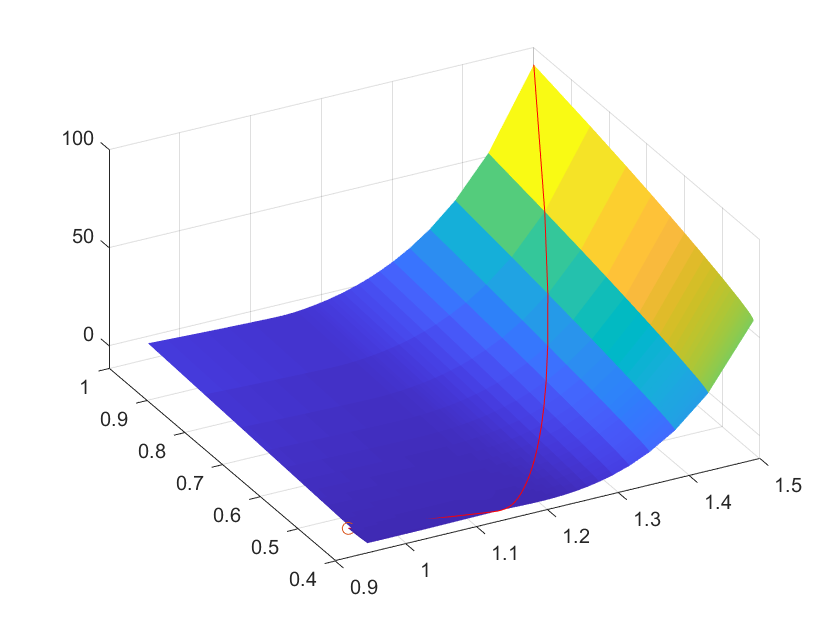

s.EdgeColor = 'none';
hold on
plot3(beta_1,beta_2,Q(2:end),'r')
plot3(beta_1(end),beta_2(end),Q(end),'o')

function [dQ]=deltaQ(X,y,beta)
    [n,m] = size(X);
    dQ=-2/n*(X'*y-X'*X*beta(:,end));
end

function [beta1]=betaladd1(Gamma,dQ,beta)
    beta1=beta(:,end)-Gamma*dQ(:,end).*beta(:,end);
end

function [a]=acti(beta,X)
    a=beta(:,end)'*X';
end

function [Q]=likelihood(y,X,beta)
    [n,m] = size(y);
    Q=1/n*sum((y-acti(beta,X))^2,'all');
end

function [pQ]=deriQ(y,X,B)
    [k,m] = size(y);
    pQ=-2/k*sum((y-X*B)'*X(1:k,2:2),'all');

end